# Practical 2 - Colour Image Segmentation and Binary Images 

clear all;
close all;
clc;

%------------------------------------------------------------

## Task 1

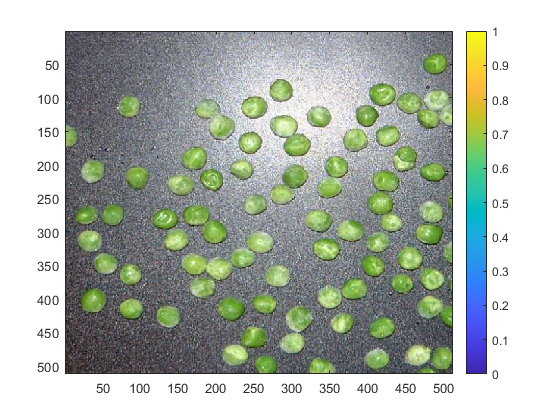

%read image
IM=imread('croppedpeasondesk.jpg');
figure;
image(IM);colorbar;

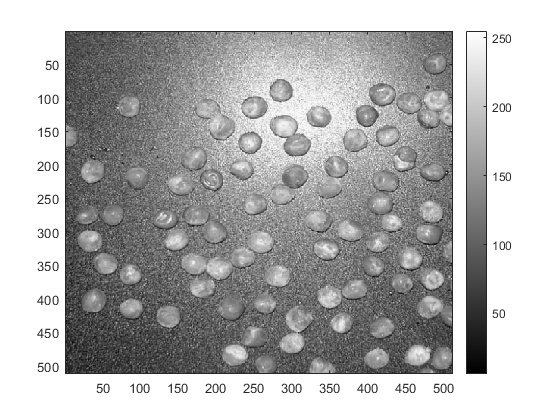


%convert to grayscale
G=rgb2gray(IM);
figure
imagesc(G); colormap(gray(256)); colorbar;


%create histogram
G=double(G);
g=G(:); %1-D array

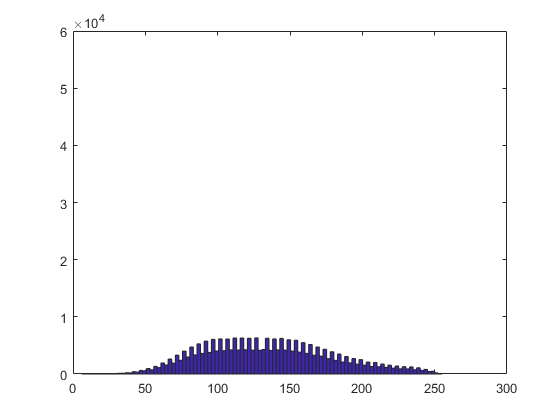

figure;
bins=100;
hist(g,bins);
ylim([0,60000])

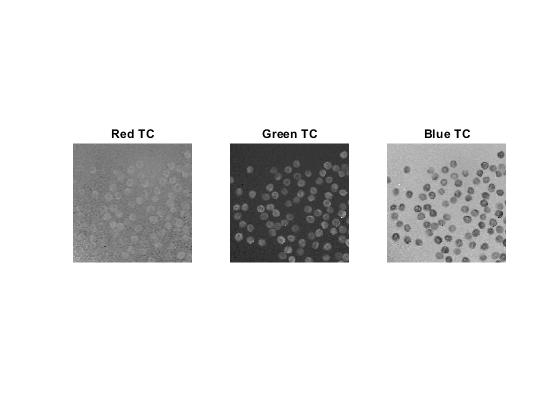

% the following computes the trchromatic coefficients
X = double(IM);
rc = X(:,:,1)./sum(X,3); % sum over r,g,b components in denominator
gc = X(:,:,2)./sum(X,3);
bc = X(:,:,3)./sum(X,3);

figure;colormap(gray(256));
subplot(1,3,1); imagesc(rc); title('Red TC');axis square; axis off
subplot(1,3,2); imagesc(gc);title('Green TC');axis square; axis off
subplot(1,3,3); imagesc(bc);title('Blue TC');axis square; axis off

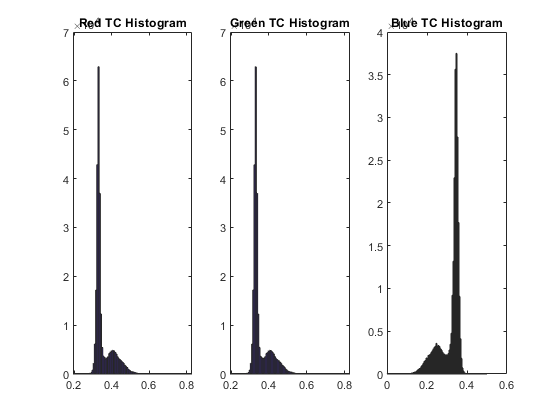


figure;
subplot(1,3,1);hist(gc(:),bins);title('Red TC Histogram')
subplot(1,3,2);hist(gc(:),bins);title('Green TC Histogram')
subplot(1,3,3);hist(bc(:),bins);title('Blue TC Histogram')

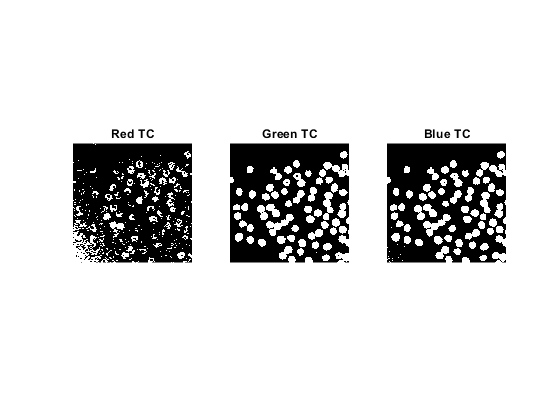


figure; colormap(gray(64));%binary images from each channel
subplot(1,3,1); imagesc(rc>0.34); title('Red TC');axis square; axis off
subplot(1,3,2); imagesc(gc>0.368);title('Green TC');axis square; axis off
subplot(1,3,3); imagesc(bc<0.3);title('Blue TC');axis square; axis off

## Task 2

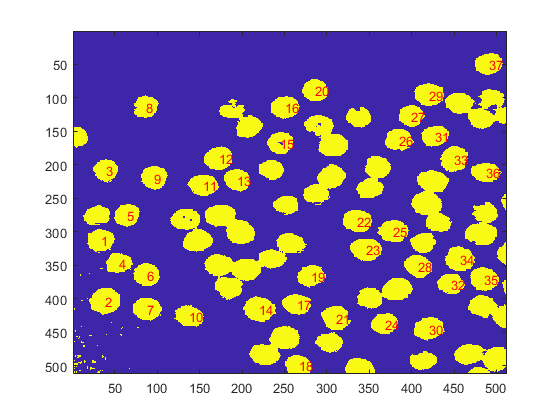

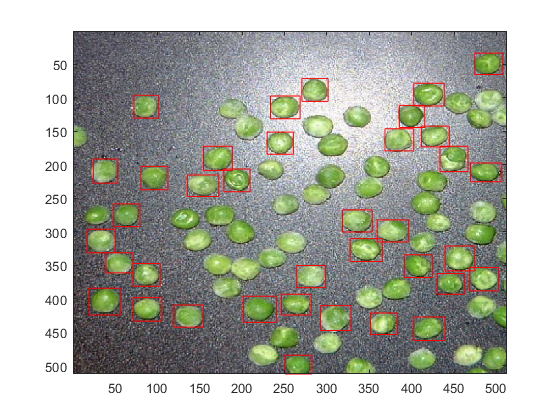

bbc=bc<0.3;
figure;
imagesc(bbc);

bbclabeled = bwlabel(bbc,double("8"));%label regions

Regions = regionprops(bbclabeled);

PeaRegions = [];
for i = 1:length(Regions)
    if (Regions(i).Area >700) & (Regions(i).Area < 1250)
        PeaRegions = [PeaRegions, Regions(i)];
        
    end
end

figure;
imagesc(IM);
for i = 1:length(PeaRegions)
    figure(8)
    h=rectangle('Position',PeaRegions(i).BoundingBox);
    set(h,'EdgeColor','r');
    xc=PeaRegions(i).Centroid(1);
    yc=PeaRegions(i).Centroid(2);
    figure(7)
    h=text(xc,yc,num2str(i));
    set(h,'color','r');
end

detected_regions=length(PeaRegions)

detected_regions = 37

total_regions=length(Regions)

total_regions = 125

## `Task 3 - The average pea`

N_peas=length(PeaRegions);
areas=cat(1,PeaRegions.Area);
boxes=cat(1,PeaRegions.BoundingBox);
boxes=boxes(:,3:4); %keep only dimensions
centers=cat(1,PeaRegions.Centroid);


[max_area,max_I]=max(areas);

LargestPea=PeaRegions(max_I);
BigBox=LargestPea.BoundingBox(3:4);

T1=[-BigBox(2)/2, -BigBox(1)/2];
T2=[BigBox(2), BigBox(1)];
bound_check=[0,0;-size(IM,1)-1,-size(IM,2)-1];


numPeasNotOnBoundary=0;

for i = 1:length(PeaRegions)
    bounds=floor(PeaRegions(i).Centroid+T1);
    bounds=[bounds;-(bounds+T2)];
    if (sum(bounds > bound_check,'all')==4)
        numPeasNotOnBoundary = numPeasNotOnBoundary+1;
        PeaStack(:,:,:,numPeasNotOnBoundary) = IM(bounds(1,2):-bounds(2,2),bounds(1,1):-bounds(2,1),1:3);
    end
    
end

size(PeaStack)

ans =     38    41     3    36


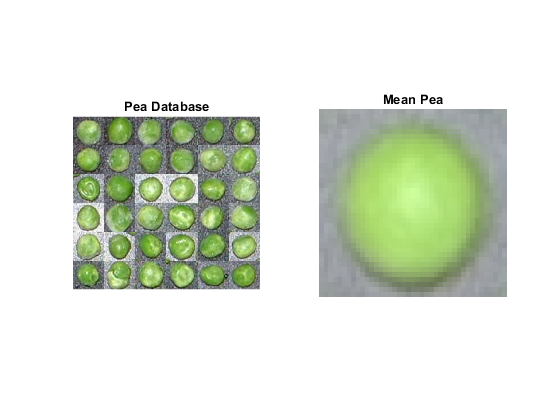


figure;
subplot(1,2,1);
montage(PeaStack);title('Pea Database');
MeanPeaTrueColour=mean(PeaStack,4);
MeanPeaTrueColour = MeanPeaTrueColour./max(MeanPeaTrueColour(:));
subplot(1,2,2);
imagesc(MeanPeaTrueColour);axis square; axis off
title('Mean Pea');